# RefMap tonality/tonal loudness proxy metric development

## Setup

Last modified: 06/11/2025

Comments: Initialised

% choose SHM ECMA-418-2 directory for processing
shmPath = uigetdir("", "Select ECMA-418-2 refmap-psychoacoustics\src\mlab\ root directory");
addpath(genpath(shmPath))

% choose input directory for audio files
inPath = uigetdir("", "Select input directory \02 Delivery\Psychoacoustic metrics\From_Carlos\SynthesisedHovering");
addpath(inPath)

% select audio files
[inFiles, inFilepath] = uigetfile("*.wav", "Select wav files from \02 Delivery\Psychoacoustic metrics\From_Carlos\SynthesisedHovering", inPath, "MultiSelect", "on");
inFilepaths = string(fullfile(inFilepath, inFiles));

% time skips
start_skip = 0.5;
end_skip = 0.5;

% custom colour palette for line plotting
mycolours = [0, 102, 255;
             0, 204, 153;
             255, 0, 102;
             74, 111, 152;
             231, 144, 29; %251, 164, 49;
             204, 153, 255;
             90, 192, 255;
             90, 255, 243;
             255, 110, 212;
             164, 201, 242;
             255, 254, 139;
             255, 243, 255]./255;

## Process files

% create audio datastore object
ads = audioDatastore(fullfile(inFilepaths));
[~, readInfo] = read(ads);
sampleRate = readInfo.SampleRate;

% Create transform datastores that calculate metric outputs after reading data
% from file:
fdsTECMA = transform(ads, @(signalIn)acousticSHMTonality(signalIn, sampleRate, 1, 'diffuse', false, false));
fdsNQZ4182 = transform(ads, @(signalIn)acousticQuasiLoudZwickerWav(signalIn, sampleRate, 0.1, 1, 'diffuse', 'ecma4182'));

% parallel read all filtered audio using transform datastores
TonalECMA = readall(fdsTECMA, UseParallel=true);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.


LoudQZ4182 = readall(fdsNQZ4182, UseParallel=true);

% loop through tonality output and calculate loudness
for ii = length(ads.Files):-1:1
    LoudECMA(ii) = acousticSHMLoudnessFromComponent(TonalECMA(ii).specTonalLoudness, TonalECMA(ii).specNoiseLoudness, false, false);
end


% calculate total tonal loudness for ECMA-processed files
[loudTDep, loudness] = cellfun(@loudOverall, {TonalECMA.specTonalLoudness}, 'UniformOutput', false);
[TonalECMA.tonalLoudPowAvg] = loudness{:};
[TonalECMA.tonalLoudTDep] = loudTDep{:};

[loudTDep, loudness] = cellfun(@loudOverall, {TonalECMA.specNoiseLoudness}, 'UniformOutput', false);
[TonalECMA.bBandLoudPowAvg] = loudness{:};
[TonalECMA.bBandLoudTDep] = loudTDep{:};


## Compare tonal loudnesses

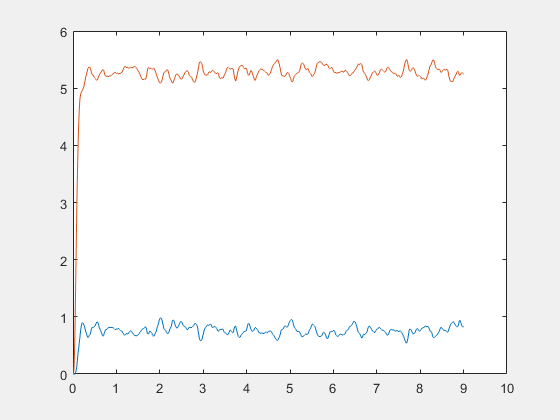

aurMask = contains(ads.Files, "_Aur");
tonalMask = contains(ads.Files, "Tonal");
bBandMask = contains(ads.Files, "BroadBand");

TonalECMAAur = TonalECMA(aurMask);
LoudQZ4182Tonal = LoudQZ4182(tonalMask);
LoudQZ4182BBand = LoudQZ4182(bBandMask);
fileNames = ads.Files(aurMask);

figure
scatter([LoudQZ4182Tonal.loudPowAvg], [TonalECMAAur.tonalLoudPowAvg], 'DisplayName', "Tonal loudness")
% legend('Location', 'northwest')
ylabel("Tonal loudness $N_T$ (Sottek Hearing Model), sone$_\mathrm{SHM}$", 'Interpreter', 'latex')
xlabel(["Quasi-loudness of separated tonal component,"; "sone$_\mathrm{QZ+ECMA}$"], 'Interpreter', 'latex')
grid('on')
set(gca, 'FontName', 'Times New Roman', 'GridAlpha', 0.05')

for ii = 1:sum(tonalMask)
    fig = figure;
    fig.Visible = 'on';
    movegui(fig, 'center')
    plot(TonalECMAAur(ii).timeOut, TonalECMAAur(ii).tonalLoudTDep, 'DisplayName', "Tonal loudness (SHM)")
    hold on
    plot(TonalECMAAur(ii).timeOut, TonalECMAAur(ii).bBandLoudTDep, 'DisplayName', "Noise loudness (SHM)")
    plot(LoudQZ4182Tonal(ii).timeOut, LoudQZ4182Tonal(ii).loudTDep, 'DisplayName', "Loudness of tonal component (QZ + ECMA-418-2)")
    plot(LoudQZ4182BBand(ii).timeOut, LoudQZ4182BBand(ii).loudTDep, 'DisplayName', "Loudness of broadband component (QZ + ECMA-418-2)")
    xlabel("Time, s")
    ylabel("Loudness, sone")
    axis([0, 9, 0, 30])
    legend('Location', 'northoutside')
    [~, fileName, ~] = fileparts(fileNames(ii));
    title(extractBefore(fileName, "_"))

    fig = figure;
    fig.Visible = 'on';
    movegui(fig, 'center')
    plot(TonalECMAAur(ii).timeOut, TonalECMAAur(ii).tonalLoudTDep./TonalECMAAur(ii).bBandLoudTDep,...
         'DisplayName', "Tonal/bband loudness (SHM)")
    hold on
    plot(LoudQZ4182BBand(ii).timeOut, LoudQZ4182Tonal(ii).loudTDep./LoudQZ4182BBand(ii).loudTDep,...
         'DisplayName', "Tonal/bband loudness component (QZ + ECMA-418-2)")
    xlabel("Time, s")
    ylabel("Loudness ratio")
    axis([0, 9, 0, 1])
    legend('Location', 'northoutside')
    [~, fileName, ~] = fileparts(fileNames(ii));
    title(extractBefore(fileName, "_"))

end

## Helper functions

function [loudTDep, loudness] = loudOverall(specLoud)
    loudTDep = sum(specLoud, 2)*0.5;
    loudness = (sum(loudTDep((57 + 1):end, :).^(1/log10(2)), 1)./size(loudTDep((57 + 1):end, :), 1)).^log10(2);
end
